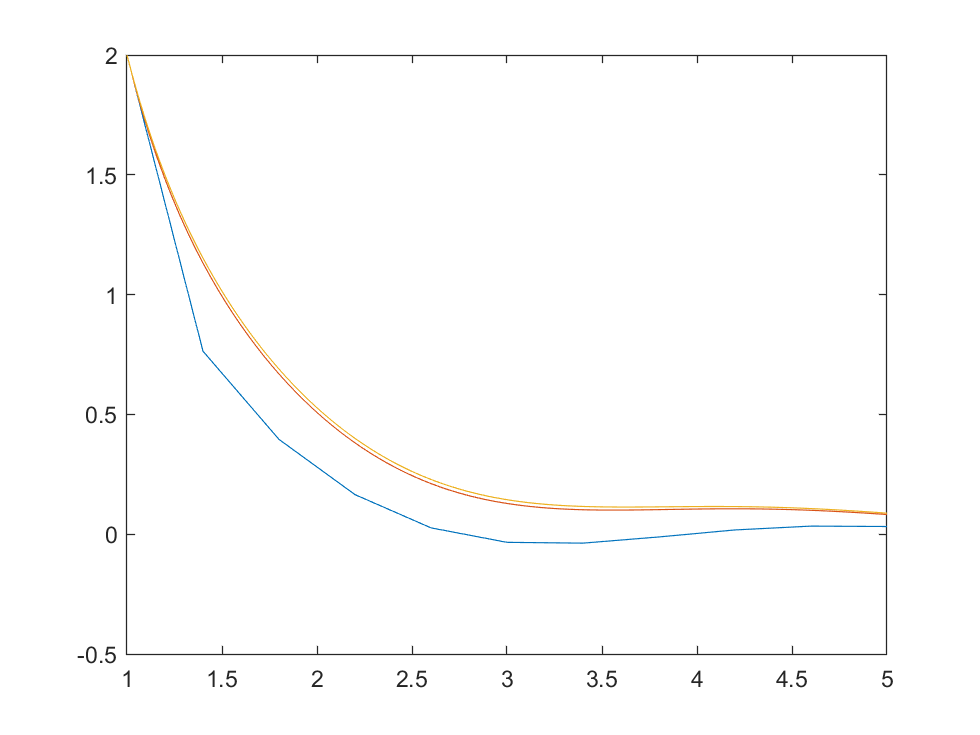

f =@(t,y) (sin(2*t)-2*t*y)/(t^2);

a = 1;
b = 5;

alpha = 2;

N = [10,10^2,10^3];

y0 = euler_timestep(f,a,b,alpha,N(1,1));
y1 = euler_timestep(f,a,b,alpha,N(1,2));
y2 = euler_timestep(f,a,b,alpha,N(1,3));

x0 = (b-a)/N(1,1);
x1 = (b-a)/N(1,2);
x2 = (b-a)/N(1,3);

t0 = a:x0:b;
t1 = a:x1:b;
t2 = a:x2:b;

t0 = t0';
t1 = t1';
t2 = t2';

plot(t0,y0,t1,y1,t2,y2);

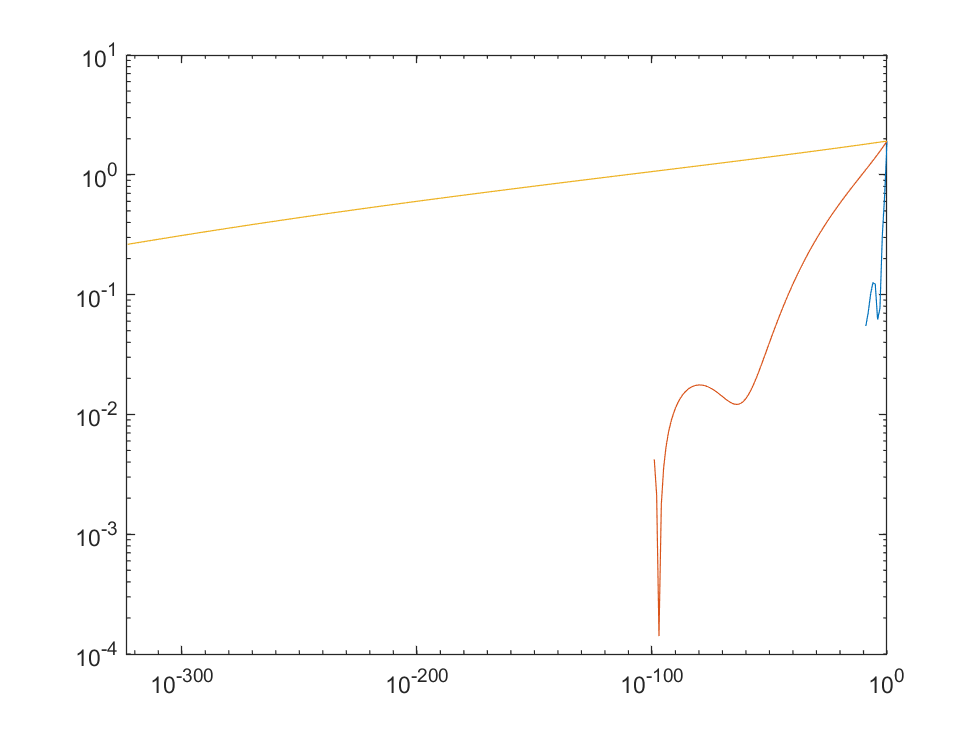


% the answer gets more accurate as the number of intervals increases

%{
syms y(t)
eqn = diff(y,t) == (sin(2*t)-2*t*y)/(t^2);
cond = y(1) == alpha;
ySol(t) = dsolve(eqn,cond);

eans = vpa(ySol(5));
%}

eans = 8.845849e-02;

h0 = ones(1,N(1,1));
h1 = ones(1,N(1,2));
h2 = ones(1,N(1,3));

err0 = ones(1,N(1,1));
err1 = ones(1,N(1,2));
err2 = ones(1,N(1,3));

% absolute error of 10 intervals
for i = 1:N(1,1)
    h0(1,i) = 10^(1-i);
    err0(1,i) = abs(eans-y0(i,1));
end

% absolute error of !0^2 intervals
for i = 1:N(1,2)
    h1(1,i) = 10^(1-i);
    err1(1,i) = abs(eans-y1(i,1));
end

% absolute error of 10^3 intervals
for i = 1:N(1,3)
    h2(1,i) = 10^(1-i);
    err2(1,i) = abs(eans-y2(i,1));
end

loglog(h0,err0);
hold on;
loglog(h1,err1);
loglog(h2,err2);
hold off;


% the error decreases as the number of intervals increases


function [y] = euler_timestep(f,a,b,alpha,N)
    h = (b-a)/N;
    x = a:h:b;
    sx = size(x,2);
    y = ones(1,sx);
    y(1,1) = alpha;
    for i = 2:N+1
        y(1,i) = y(1,i-1) + h*f(x(1,i-1),y(1,i-1));
    end
    y = y';
end
